clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


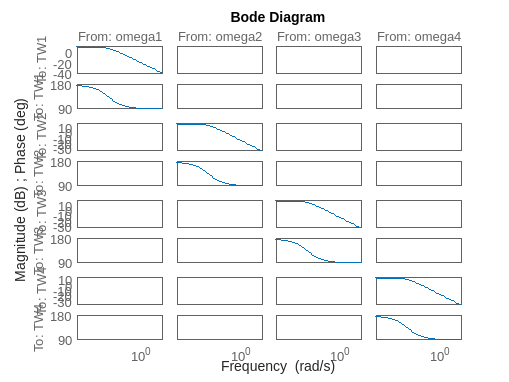




Hvac = ss(param.model.A,[param.model.B_Bar, blkdiag([0;1;0],[0;1;0],[0;1;0],[0;1;0]);],eye(12),0);
Hvac.StateName = {'TW1';'TA1';'delta1';'TW2';'TA2';'delta2';'TW3';'TA3';'delta3';'TW4';'TA4';'delta4'};
Hvac.InputName = {'omega1';'omega2';'omega3';'omega4';'r1';'r2';'r3';'r4'};
Hvac.OutputName = {'TW1';'TA1';'delta1';'TW2';'TA2';'delta2';'TW3';'TA3';'delta3';'TW4';'TA4';'delta4'};


bode(Hvac({'TW1','TW2','TW3','TW4'},{'omega1','omega2','omega3','omega4'}))

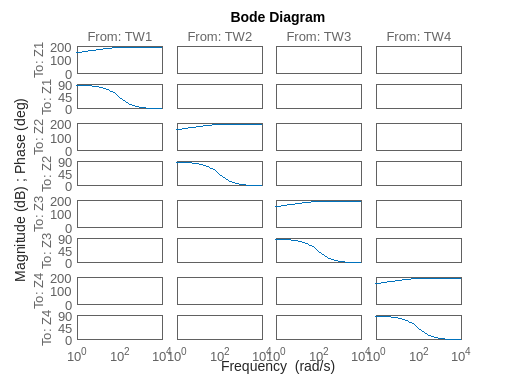


Actnorm = eye(4);
Wunc = eye(4);
unc = ultidyn('unc',[4 4],'SampleStateDim',5);
Act = Actnorm*(eye(4) + Wunc*unc);
Act.InputName = {'omega1k';'omega2k';'omega3k';'omega4k'};
Act.OutputName ={'omega1';'omega2';'omega3';'omega4'};

wz = 10000*eye(4)*tf([10000,1],[1e-2,1]);
wz.InputName = {'TW1';'TW2';'TW3';'TW4'};
wz.OutputName = {'Z1';'Z2';'Z3';'Z4'}; 
bode(wz)


% rng('default')
% bode(Act,'b',Act.NominalValue,'r+',logspace(-1,3,120))
ICinputs =  {'r1';'r2';'r3';'r4';'omega1k';'omega2k';'omega3k';'omega4k'};
ICOutputs = {'Z1';'Z2';'Z3';'Z4';'TW1';'TA1';'delta1';'TW2';'TA2';'delta2';'TW3';'TA3';'delta3';'TW4';'TA4';'delta4'}

ICOutputs = 16×1 cell array
    {'Z1'    }
    {'Z2'    }
    {'Z3'    }
    {'Z4'    }
    {'TW1'   }
    {'TA1'   }
    {'delta1'}
    {'TW2'   }
    {'TA2'   }
    {'delta2'}
    {'TW3'   }
    {'TA3'   }
    {'delta3'}
    {'TW4'   }
    {'TA4'   }
    {'delta4'}


HvacIC = connect(Hvac,Act,wz,ICinputs,ICOutputs)

Uncertain continuous-time state-space model with 16 outputs, 8 inputs, 16 states.
The model uncertainty consists of the following blocks:
  unc: Uncertain 4x4 LTI, peak gain = 1, 1 occurrences


    
ncont = 4; % one control signal, u
nmeas = 12; % two measurement signals, sd and ab
K = ss(zeros(ncont,nmeas));
gamma = 0;
opts = hinfsynOptions('Display','on');
  [K(:,:),~,gamma] = hinfsyn(HvacIC,nmeas,ncont,opts)


  Test bounds:  4.12e+03 <=  gamma  <=  8.8e+03

   gamma        X>=0        Y>=0       rho(XY)<1    p/f
  6.02e+03     1.0e+01     8.7e-23     6.194e-12     p
  4.98e+03    -2.3e+05     8.6e-23     3.029e-12     f
  5.48e+03    -8.4e+05 #   8.7e-23     1.531e-12     f
  5.74e+03    -4.0e+07 #   8.6e-23     1.206e-12     f
  5.88e+03     1.0e+01     8.6e-23     1.266e-11     p
  5.81e+03     1.0e+01     8.6e-23     2.659e-11     p
  5.78e+03     1.0e+01     8.7e-23     5.926e-11     p
  Repairing inconsistencies...
  6.35e+03     1.0e+01     8.6e-23     2.856e-12     p
  6.35e+03     1.0e+01     8.7e-21     2.870e-11     p
  6.35e+03     1.0e+01     8.6e-19     2.861e-10     p
  6.35e+03     1.0e+01     8.6e-17     2.912e-09     p
  Limiting gains...
  6.35e+03     1.0e+03     4.4e-14     2.239e-06     p
  6.35e+03    -5.2e+05     4.4e-14     2.362e-05     f

  Best performance (actual): 5.29e+03

K =
 
  A = 
                x1          x2          x3          x4          x5         

gamma = 5.2876e+03


gamma

gamma = 5.2876e+03

K.u = {'TW1';'TA1';'delta1';'TW2';'TA2';'delta2';'TW3';'TA3';'delta3';'TW4';'TA4';'delta4'};  K.y = {'omega1k';'omega2k';'omega3k';'omega4k'};
CL = connect(Hvac,Act.Nominal,K,{'r1';'r2';'r3';'r4'},wz.InputName);
t = 0:0.0025:10;
u = zeros(length(t),4);
u(100:end,:) =ones(length(t)-99,4); 

% bode(CL)

% [Krob,rpMU] = musyn(HvacIC,nmeas,ncont)

clear 
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties



G = 1.2*tf([1,1],[1,1])

G =
 
  1.2 s + 1.2
  -----------
     s + 1
 
Continuous-time transfer function.
Model Properties



[A,B,C,D]=tf2ss(1.2*[1,1],[1,1])

A = -1

B = 1

C = 0

D = 1.2000


[num,den] = ss2tf(A,B,C,D)

num =     1.2000    1.2000


den =      1     1



G1 = tf(num,den)

G1 =
 
  1.2 s + 1.2
  -----------
     s + 1
 
Continuous-time transfer function.
Model Properties
